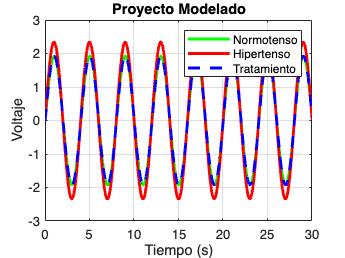

% Nombre del modelo (asegúrate que coincida con el nombre del archivo Simulink)
modelName = 'ProyectooModelado';

% Ejecutar la simulación
sim(modelName);

% Cargar datos del workspace
t = normotenso.time;  % Tiempo común para todas las señales
y_normotenso = normotenso.signals.values;
y_hipertenso = hipertenso.signals.values;
y_tratamiento = tratamiento.signals.values;


% Graficar las señales
figure;
plot(t, y_normotenso, 'g', 'LineWidth', 2, 'DisplayName', 'Normotenso'); hold on;
plot(t, y_hipertenso, 'r', 'LineWidth', 2, 'DisplayName', 'Hipertenso');
plot(t, y_tratamiento, 'b--', 'LineWidth', 2, 'DisplayName', 'Tratamiento');

% Configurar la gráfica
title('Proyecto Modelado');
xlabel('Tiempo (s)');
ylabel('Voltaje');
legend show;
grid on;

exportgraphics(gcf,'Proyecto.pdf','ContentType','Vector')